## Multi- ROSBAG processing for Clemson Clearpath Husky

### Parsing ROSBAGS

**1.Create an empty directory as a workspace and have this mlx. script along with the***** extractData.m***** function within the workspace. Provide path to the directory that contains all the rosbags.**

clc
clear

%permanent location : https://drive.google.com/drive/folders/1R5kQL7F6gGLBh3oBs8bkDhJhJy0m1kB7?usp=drive_link

abs_path = 'C:\Users\asalvi\Downloads\ExtSkidPad\'; %  <-------- Path to ROSBAGS directory on your system


strcat(abs_path,'*.*');

Files=dir(strcat(abs_path,'*.*'));
for k=1:length(Files)
   FileNames=Files(k).name
end

FileNames = '.'

FileNames = '..'

FileNames = 'v_0p1_c_2024-09-23-13-49-12.bag'

FileNames = 'v_0p1_cc_2024-09-23-13-48-09.bag'

FileNames = 'v_0p2_c_2024-09-23-13-47-04.bag'

FileNames = 'v_0p2_cc_2024-09-23-13-46-08.bag'

FileNames = 'v_0p3_c_2024-09-23-13-44-34.bag'

FileNames = 'v_0p3_cc_2024-09-23-13-43-36.bag'

FileNames = 'v_0p4_c_2024-09-23-13-42-32.bag'

FileNames = 'v_0p4_cc_2024-09-23-13-41-30.bag'

FileNames = 'v_0p5_c_2024-09-21-18-04-54.bag'

FileNames = 'v_0p5_cc_2024-09-21-18-03-59.bag'

FileNames = 'v_0p6_c_2024-09-21-18-02-39.bag'

FileNames = 'v_0p6_cc_2024-09-21-18-01-42.bag'

FileNames = 'v_0p7_c_2024-09-21-18-00-30.bag'

FileNames = 'v_0p7_cc_2024-09-21-17-58-43.bag'

FileNames = 'v_0p8_c_2024-09-21-17-57-23.bag'

FileNames = 'v_0p8_cc_2024-09-21-17-56-30.bag'

FileNames = 'v_0p9_c_2024-09-21-17-54-23.bag'

FileNames = 'v_0p9_cc_2024-09-21-17-53-24.bag'

FileNames = 'v_1.0_c_2024-09-21-17-52-02.bag'

FileNames = 'v_1.0_cc_2024-09-21-17-50-17.bag'

FileNames = 'v_1.0_cc_2024-09-21-17-50-59.bag'

FileNames = 'w_0p1_c_2024-09-23-13-53-16.bag'

FileNames = 'w_0p1_cc_2024-09-23-13-52-18.bag'

FileNames = 'w_0p2_c_2024-09-23-13-56-07.bag'

FileNames = 'w_0p2_cc_2024-09-23-13-54-12.bag'

FileNames = 'w_0p2_cc_2024-09-23-13-54-57.bag'

FileNames = 'w_0p3_c_2024-09-23-15-57-07.bag'

FileNames = 'w_0p3_cc_2024-09-23-15-55-57.bag'

FileNames = 'w_0p4_c_2024-09-23-15-59-26.bag'

FileNames = 'w_0p4_cc_2024-09-23-15-58-14.bag'

FileNames = 'w_0p5_c_2024-09-23-16-01-44.bag'

FileNames = 'w_0p5_cc_2024-09-23-16-00-46.bag'

FileNames = 'w_0p6_c_2024-09-23-16-03-58.bag'

FileNames = 'w_0p6_cc_2024-09-23-16-03-02.bag'

FileNames = 'w_0p7_c_2024-09-23-16-05-44.bag'

FileNames = 'w_0p7_cc_2024-09-23-16-04-54.bag'

FileNames = 'w_0p8_c_2024-09-23-18-00-28.bag'

FileNames = 'w_0p8_cc_2024-09-23-17-59-37.bag'

FileNames = 'w_0p8_cc_2024-09-23-18-01-20.bag'

FileNames = 'w_0p9_c_2024-09-23-18-02-24.bag'

FileNames = 'w_0p9_cc_2024-09-23-18-03-09.bag'

FileNames = 'w_1p0_c_2024-09-23-18-04-05.bag'

FileNames = 'w_1p0_cc_2024-09-23-18-04-55.bag'

**2. Parse all the rosbags and save them as a matlab readable structure. **

**Once the bags are converted to structure, see what all are the available topics.**

for k=1:length(Files)-2
   bag(k)= rosbag(strcat(abs_path,Files(k+2).name));
end

         at line 278 in B:\3p\derived\win64\ros1\src\geometry2\tf2\src\buffer_core.cpp
         at line 278 in B:\3p\derived\win64\ros1\src\geometry2\tf2\src\buffer_core.cpp
         at line 278 in B:\3p\derived\win64\ros1\src\geometry2\tf2\src\buffer_core.cpp
         at line 278 in B:\3p\derived\win64\ros1\src\geometry2\tf2\src\buffer_core.cpp


% Print available topics:
bag(1, 1).AvailableTopics

ans = 53×3 table
                                                         NumMessages                 MessageType                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                        MessageDefinition                           

**3. You can choose which of the available topics you want to extract. Set the variable as '1' for all the topics you want to be extracted. Latest available topics 09/15/2025**

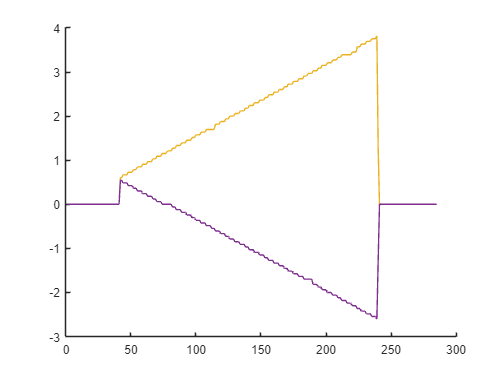

% chose topics out of available topics (true =1 , false =0)

which_topic.tf = 1;
which_topic.gps_head = 0;
which_topic.gps_pos = 0;
which_topic.imu = 1;
which_topic.imu_fil = 1 ;
which_topic.js = 1;
which_topic.cmd_vel = 1;
which_topic.odom = 1;
which_topic.axis_camera = 1;
which_topic.realsense_camera_rgb = 0;
which_topic.realsense_camera_d = 0;
which_topic.camera_pan = 0;
which_topic.axis_info = 0;
which_topic.status = 0;
which_topic.usb_cam = 1;
which_topic.april_pose = 1;


**4. Parse the topics. A folders called 'imgs_bag_no' will be created and .jpg format images will be stored in that folder if you choos *****axis_camera***** topic as true.**

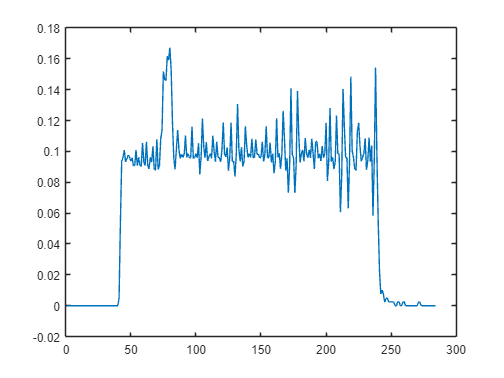

for k=1:length(Files)-2
   sensor(k) = extractData(bag(k),which_topic,pwd,k);

end


### Data Visualization

After these four steps, a structure call 'sensor' will be created for k bags you parse. Following are few examples of how to plot/ visualize data from the sensor structure:

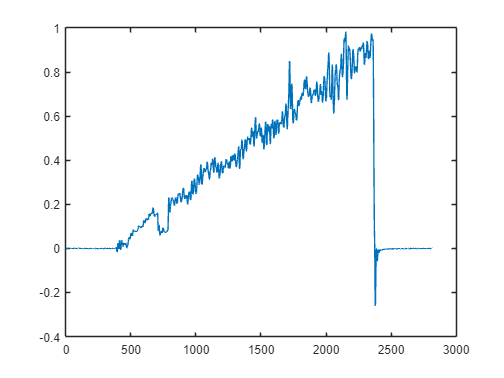

figure

hold on
plot(sensor(1).data.joint_states(1,:))
plot(sensor(1).data.joint_states(2,:))
plot(sensor(1).data.joint_states(3,:))
plot(sensor(1).data.joint_states(4,:))

figure
plot(sensor(1).data.odom_VelLinX)

figure
plot(sensor(1).data.IMU_AngZ)


### Time Sync Data (latest sync topics 9/15/2025)

Time sync data to wheel velocity signals

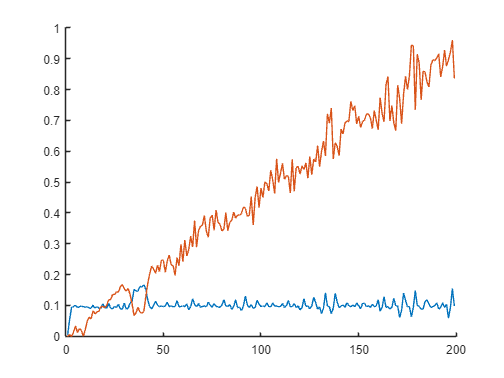

Sync_topics.odom_VelLinX = 1;
Sync_topics.odom_pos = 1;
Sync_topics.gps = 0;
Sync_topics.IMU_fil_AngZ = 1;
Sync_topics.gps_head = 0;
Sync_topics.images = 1;
Sync_topics.cam_pan = 0;
Sync_topics.rs_images =0;
Sync_topics.status = 0;

Sync_topics.IMU_AngZ = 0;
Sync_topics.IMU_LinX = 1;
Sync_topics.cmd_V = 0;
Sync_topics.cmd_OMG = 0;
Sync_topics.usb_images = 1;
Sync_topics.april_poses = 1;


TSyn = timeSync(sensor,k,Sync_topics);

Visulaize Data Synced to Wheel Velocity inputs (only the data where wheel velocity input signals are greater than zero)

k_t = find(sensor(1).data.joint_states(1,:)>0); %k_t gets the greater than zero indexes

figure
hold on
plot(TSyn(1).data.odom_VelLinX(k_t))
plot(TSyn(1).data.IMU_fil_AngZ(k_t))

Save data to CSV (As per your bags and topics, best way)

DataSet_im = [TSyn(1).data.image_no(:);TSyn(2).data.image_no(:)];
DataSet_usb_im = [TSyn(1).data.usb_image_no(:);TSyn(2).data.usb_image_no(:)];
DataSet_LinV = [TSyn(1).data.odom_VelLinX(:);TSyn(2).data.odom_VelLinX(:)];
DataSet_AngZ = [TSyn(1).data.IMU_fil_AngZ(:);TSyn(2).data.IMU_fil_AngZ(:)];
DataSet_posX = [TSyn(1).data.pos_x(:);TSyn(2).data.pos_x(:)];
DataSet_posY = [TSyn(1).data.pos_y(:);TSyn(2).data.pos_y(:)];
DataSet_aprilPX = [TSyn(1).data.april_posePX(:);TSyn(2).data.april_posePX(:)];
DataSet_aprilPY = [TSyn(1).data.april_posePY(:);TSyn(2).data.april_posePY(:)];
DataSet_aprilPZ = [TSyn(1).data.april_posePZ(:);TSyn(2).data.april_posePZ(:)];
DataSet_aprilQX = [TSyn(1).data.april_poseQX(:);TSyn(2).data.april_poseQX(:)];
DataSet_aprilQY = [TSyn(1).data.april_poseQY(:);TSyn(2).data.april_poseQY(:)];
DataSet_aprilQZ = [TSyn(1).data.april_poseQZ(:);TSyn(2).data.april_poseQZ(:)];
DataSet_aprilQW = [TSyn(1).data.april_poseQW(:);TSyn(2).data.april_poseQW(:)];


%clear DataSet
%DataSet = 

% Create the full table
T = table( ...
    DataSet_im, ...
    DataSet_usb_im,...
    DataSet_LinV, ...
    DataSet_AngZ, ...
    DataSet_posX, ...
    DataSet_posY, ...
    DataSet_aprilPX,...
    DataSet_aprilPY,...
    DataSet_aprilPZ,...
    DataSet_aprilQX,...
    DataSet_aprilQY,...
    DataSet_aprilQZ,...
    DataSet_aprilQW,...
    'VariableNames', {'target_image_path','source_image_path','lin_vel_x', 'ang_vel_z', 'pos_x', 'pos_y', 'april_PX','april_PY','april_PZ','april_QX','april_QY','april_QZ','april_QW'});

% Filter: Remove rows with zero linear velocity
%T_filtered = T(T.lin_vel_x ~= 0, :);

% Save filtered table to CSV
writetable(T, 'training_dataset.csv');